# Sample 13-5

## 辞書学習

学習辞書による画像復元

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Dictionary learning

Image restoration with learned dictionary

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

clear 
close all
import msip.download_img
msip.download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


### Original image

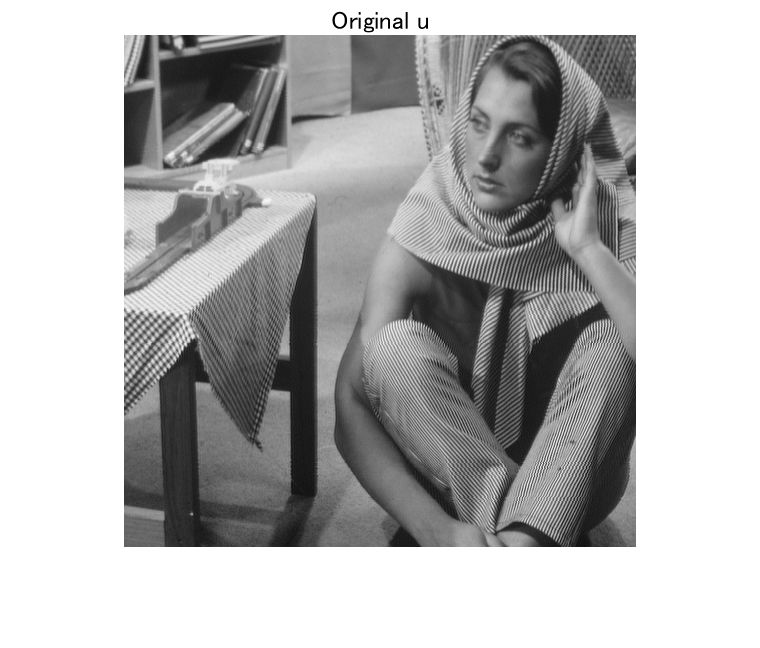

% Original image
%u = im2single(rgb2gray(imread('./data/baboon.png')));
u = im2single(imread('./data/barbara.png'));
figure(1)
imshow(u)
title('Original u')

### Observed image

Let us consider the single image super resolution problem of observation)

    
$$\mathbf{v}=\mathbf{Pu}+\mathbf{w}$$


which originates  $\mathbf{u}$ and is contaminated by additive white Gaussian noise $\mathbf{w}$ and downscale measurement proces, where $\mathbf{P}$ is a linear process consisting of low-pass filter and downsampling.

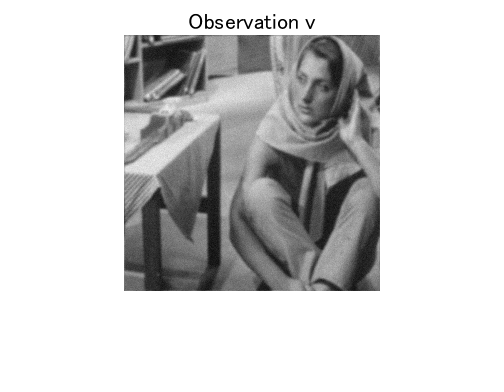

% Measurement process P
sigmah = 2;
h = fspecial('gaussian',9,sigmah);
downsample2 = @(x,m) ipermute(downsample(permute(downsample(x,m),[2 1 3]),m),[2 1 3]);
linproc = @(x) downsample2(imfilter(x,h,'conv','circ'),2);
H = fftn(h,2.^nextpow2([size(u,1) size(u,2)]));
beta = max(abs(H(:)).^2); % λmax(PP.')

% Observation
sigmaw = 5/255;
v = imnoise(linproc(u),'gaussian',0,sigmaw^2);
figure(2)
imshow(v)
title('Observation v');

## Bicubic interpolation

For the sake of reference, the result with the bicubic interpolation is shown.

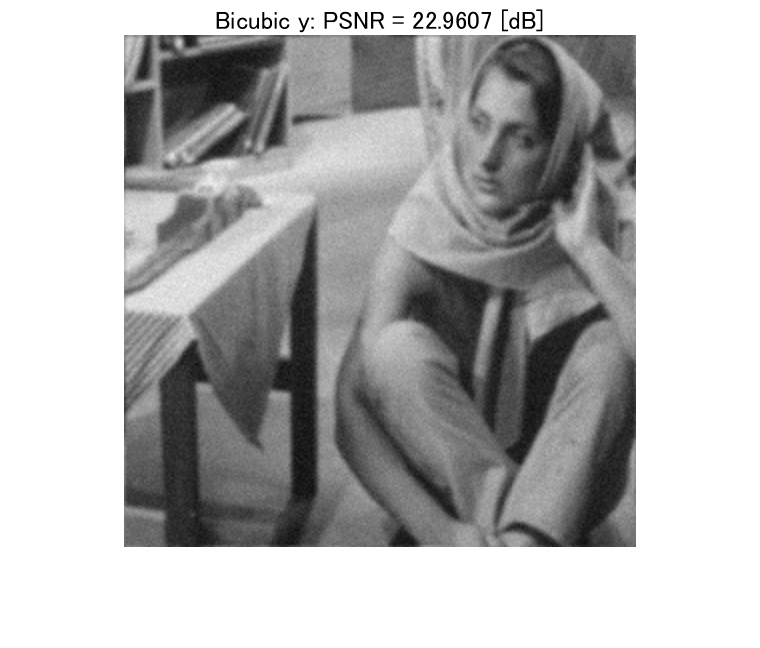

% Bicubic
y = imresize(v,2,'bicubic');
figure(3)
imshow(y)
title(['Bicubic y: PSNR = ' num2str(psnr(u,y)) ' [dB]']);

## Single image super resolution

The above denoising problem can be formulated by the  $\ell_1$-norm regularized least square problem with a redundant dictionary  $\mathbf{D}$  as

    $\hat{\mathbf{s}}=\arg\min_\mathbf{s}\frac{1}{2}\|\mathbf{v}-\mathbf{PDs}\|_2^2+\lambda\|\mathbf{s}\|_1$.

It is possible to obtain the solution by the proximal gradient algorithm

   
$$\mathbf{s}^{(t+1)}\leftarrow\mathrm{prox}_{\gamma\lambda\|\cdot\|_1}(\mathbf{s}^{(t)}-\gamma\nabla f(\mathbf{s}^{(t)}))$$


   
$$\nabla f(\mathbf{s})=\mathbf{D}^T\mathbf{P}^T(\mathbf{PDs}-\mathbf{v})$$


  $[\mathrm{prox}_{\gamma\lambda\|\cdot\|_1}(\mathbf{s})]_i=\mathcal{T}_{\gamma\lambda}([\mathbf{s}]_i)=\mathrm{sign}([\mathbf{s}]_i)\cdot\max(|[\mathbf{s}]_i|-\gamma\lambda,0)$,

where  $0<\gamma<2/\beta$ and $\beta$ is the Lipschitz constant of $\nabla f$.

In the following, let us perform single image super-resolution (SISR) with a proximal gradient method using the nonseparate oversampled laped transform (NSOLT) trained in Sample 13-4 as a dictionary.

Since  $\mathbf{DD}^T=\mathbf{I}$ holds,   $\beta=\lambda_\mathrm{max}(\mathbf{D}^T\mathbf{P}^T\mathbf{PD})=
(\mathbf{PD}\mathbf{D}^T\mathbf{P}^T)=
(\mathbf{P}\mathbf{P}^T)=\lambda_\mathrm{max}(\mathbf{PP}^T)=\sigma_\mathrm{max}^2(\mathbf{P})$.

The design data of NSOLT is saved in "nsoltdictionary.mat" under the folder "data".

### Loading NSOLT dictionary

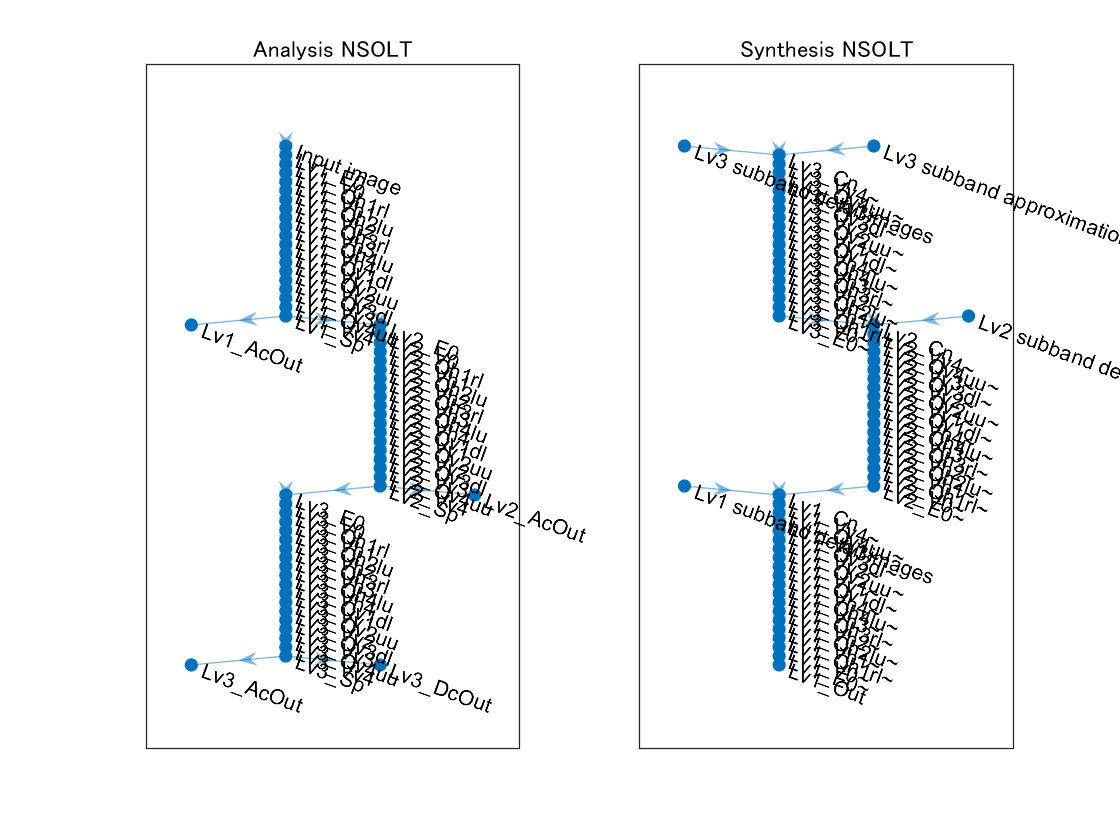

import msip.*
load ./data/nsoltdictionary.mat
analysislgraph = layerGraph(analysisnet);
synthesislgraph = layerGraph(synthesisnet);

figure(4)
subplot(1,2,1)
plot(analysislgraph)
title('Analysis NSOLT')
subplot(1,2,2)
plot(synthesislgraph)
title('Synthesis NSOLT')

Reshape the atoms into atomic images

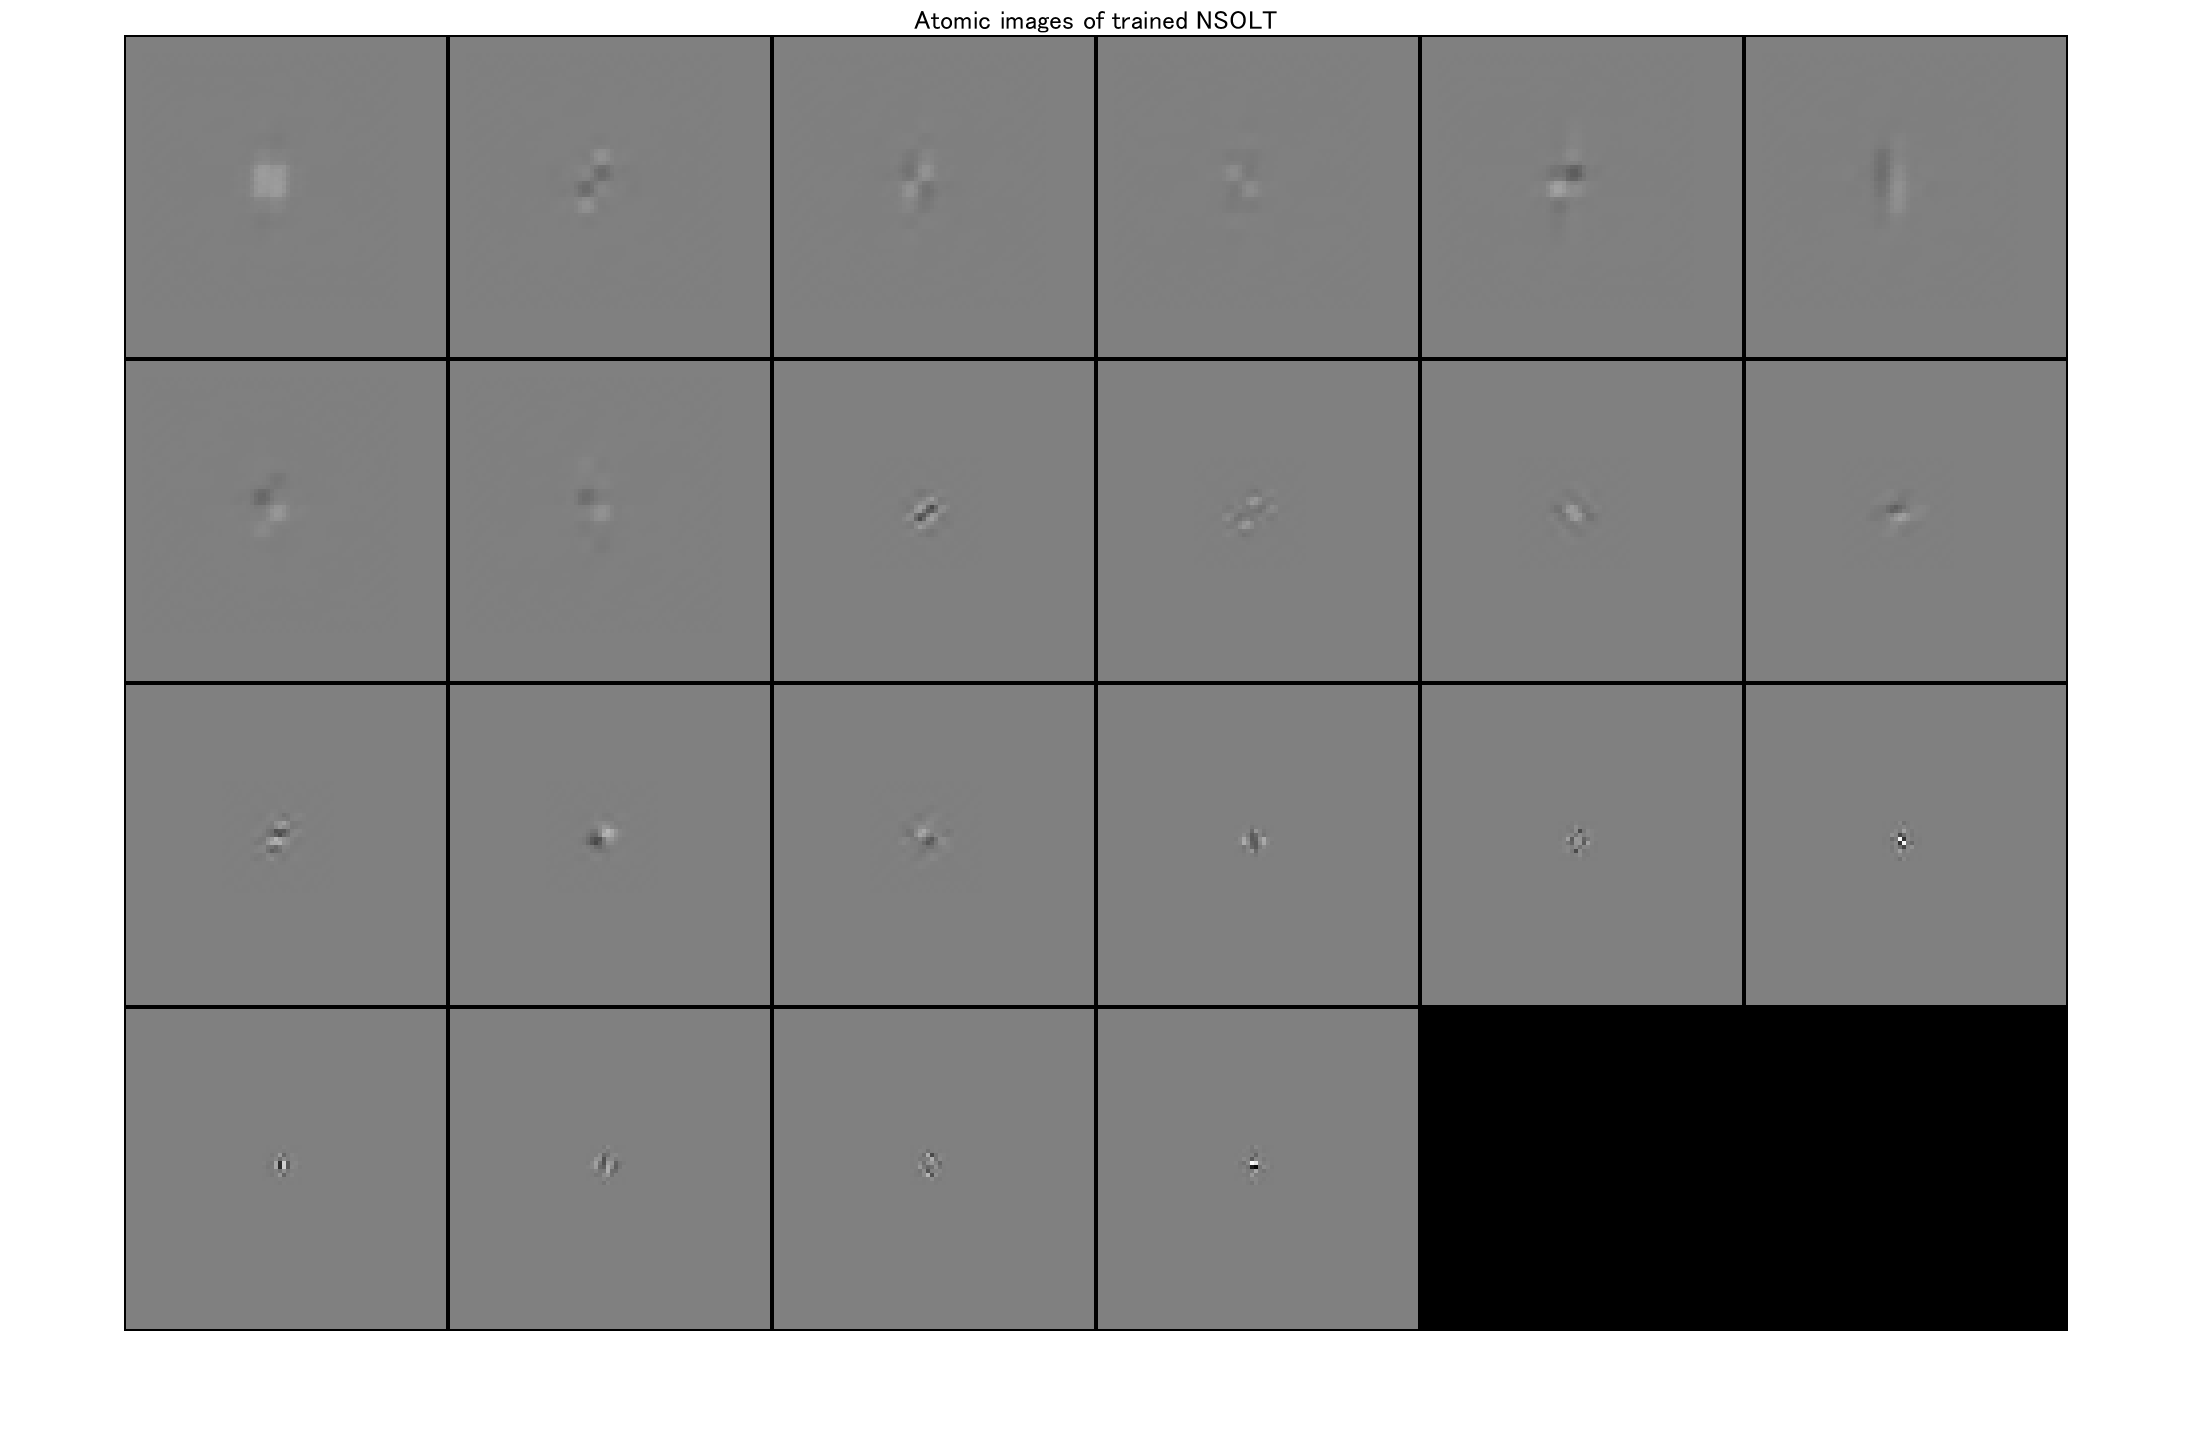

figure(5)
atomicimshow(synthesisnet)
title('Atomic images of trained NSOLT')

import msip.*
analysislgraph = analysislgraph.replaceLayer('Input image',...
        imageInputLayer(size(y),'Name','Input image','Normalization','none'));
for iLayer = 1:length(analysislgraph.Layers)
    layer = analysislgraph.Layers(iLayer);
    %{
    if strcmp(layer.Name,'Sb_Srz')
        newsrzlayer = layer.setOriginalDimension(size(y));
        analysislgraph = analysislgraph.replaceLayer(...
            'Sb_Srz',newsrzlayer);
    end
    %}
    if strcmp(layer.Name,'Lv1_E0')
        decFactor = layer.DecimationFactor;
    end
    if strcmp(layer.Name,'Lv1_V0')
        nChannels = layer.NumberOfChannels;
    end
end

%isSerialize = false;
for iLayer = 1:length(synthesislgraph.Layers)
    layer = synthesislgraph.Layers(iLayer);
    %{
    if strcmp(layer.Name,'Sb_Dsz')
        newdszlayer = layer.setOriginalDimension(size(y));
        synthesislgraph = synthesislgraph.replaceLayer(...
            'Sb_Dsz',newdszlayer);
        isSerialize = true;
    end
    %}
    if contains(layer.Name,'subband detail images')
        nLevels = str2double(layer.Name(3));
        sbSize = size(y).*(decFactor.^(-nLevels));
        newsblayer = ...
            imageInputLayer([sbSize (sum(nChannels)-1)],'Name',layer.Name,'Normalization','none');
        synthesislgraph = synthesislgraph.replaceLayer(...
            layer.Name,newsblayer);
    end
end
if contains(layer.Name,'subband approximation image')
    nLevels = str2double(layer.Name(3));
    sbSize = size(y).*(decFactor.^(-nLevels));
    newsblayer = ...
        imageInputLayer([sbSize 1],'Name',layer.Name,'Normalization','none');
    synthesislgraph = synthesislgraph.replaceLayer(...
        layer.Name,newsblayer);
end

%{
if isSerialize
    synthesislgraph = synthesislgraph.replaceLayer('Subband images',...
        imageInputLayer(newdszlayer.InputSize,'Name','Subband images','Normalization','none'));
end
%}

analysisnet = dlnetwork(analysislgraph);
synthesisnet = dlnetwork(synthesislgraph);  

#### Confirmation of perfect reconstruction (adjoint relation)

x = rand(size(y),'single');
dlx = dlarray(x,'SSC'); % Deep learning array (SSC: Spatial,Spatial,Channel)
[dls{1:nLevels+1}] = analysisnet.predict(dlx);
dly = synthesisnet.predict(dls{1:nLevels+1});
display("MSE: " + num2str(mse(dlx,dly)))

    "MSE: 2.8298e-09"



#### Adjoint operator of the measurement process

% Adjoint process P.'
upsample2 = @(x,m) ipermute(upsample(permute(upsample(x,m),[2 1 3]),m),[2 1 3]);
adjproc = @(x) imfilter(upsample2(x,2),h,'corr','circ');


## Execution of proximal-gradient method (ISTA)

- "synthesisnet" and "analysisnet" are objects of "dlnetwork."

- "dlnetwork" takes "dlarray."

- Function "extractdata" is used for extracting ordinary array data from "dlarray."  

% Parameter settings
lambda = 0.0007;
gamma = 2./(beta+1e-2);
nIters = 20;
isDcSkip = true;

% Initalization
z = dlarray(zeros(size(y),'like',y),'SSC'); % Deep learning array (SSC: Spatial,Spatial,Channel)
[coefs{1:nLevels+1}] = analysisnet.predict(z);

% profile on
for itr = 1:nIters
    x = linproc(extractdata(synthesisnet.predict(coefs{1:nLevels+1})));
    [g{1:nLevels+1}] = analysisnet.predict(dlarray(adjproc(x-v),'SSC'));
    % Gradient descnet
    for iOutput = 1:nLevels+1
        coefs{iOutput} = coefs{iOutput}-gamma*g{iOutput};
        if ~isDcSkip || iOutput < nLevels+1 
            % ISTA for detail (w/o soft-thresholding for approximation components)
            coefs{iOutput} = wthresh(coefs{iOutput},'s',gamma*lambda);
        end
    end
end
% profile off
% profile viewer


% Reconstruction
r = extractdata(synthesisnet.predict(coefs{1:nLevels+1}));

### Display the result

figure(6)
imshow(r)

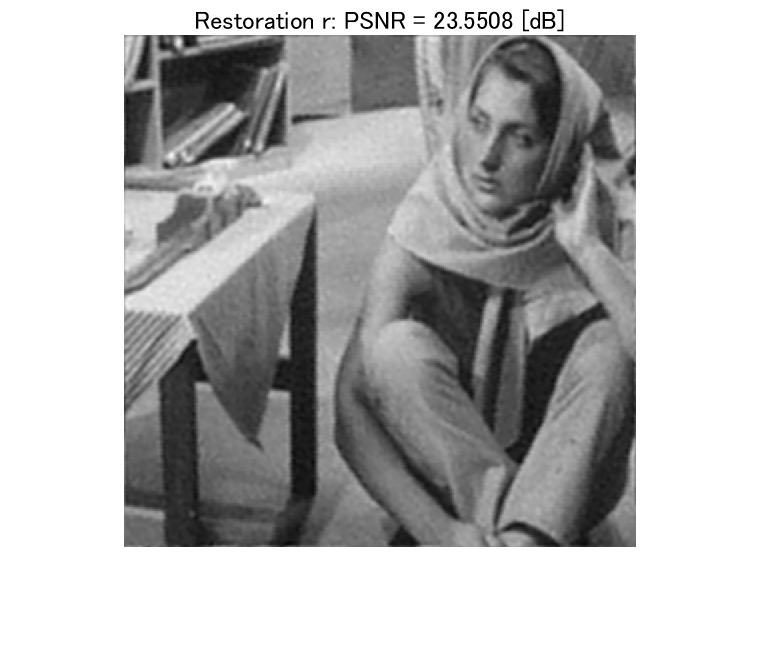

title(['Restoration r: PSNR = ' num2str(psnr(u,r)) ' [dB]'])

© Copyright, Shogo MURAMATSU, All rights reserved.